clear; close; clc;

% define equation parameters
c = 1; % wave speed
sigma = .25; % CFL number


% define computational mesh
grid_sizes = [40, 80, 160]; % number of grid point to be used

domainWidth = 10; % the width of the domain
t_end = 20; % time to stop simulation at

legendString = []; % stign for our legend


errors = zeros([1,3]);

for j = 1:length(grid_sizes)
    grid_size = grid_sizes(j);


    %grid_size = grid_sizes(1); % to be replaced with a four loop


    Delta_x = domainWidth/grid_size; % size of step in space
    Delta_t = sigma * Delta_x / c; % size of step in time from definition of CFL number

    % intitialize spacial grid
    U = zeros([grid_size + 2, t_end/Delta_t]); % add extra cels to simulate the periodic boundary condition

    % initialize with initial condition 1-cos(x), 0 <= x <= 2*pi; 0, elsewhere
    U(1 + 2 : (2*pi)/Delta_x + 2, 1) = 1 - cos([1 : (2*pi)/Delta_x] * Delta_x); % define initial condition
    %note we start from index 3 as index 1 and 2 are fro wrapping around the BC
    U(1:2,1) = U(end-1:end); % assign the wrap around values

    % we are now all configured and ready to begin computation

    % simulate system

    % initialize temporary variables
    U_star = zeros(size(U,1),1);

    % compute values for loop
    % for i = 1:t_end/Delta_t
    %     % SSP-RK2
    %     U_star(1+2:end) = U(1+2:end,i) - sigma/2 * ( 3 * U(1+2:end,i) - 4 * U(1+1:end-1,i) + U(1:end-2,i) ); % initial step
    %     U_star(1:2) = U_star(end-1:end); % update the ghost cells
    %
    %     U(1+2:end, i+1) = 1/2 * (U(1+2:end,i) + U_star(1+2:end) - sigma/2 * ( 3 * U_star(1+2:end) - 4 * U_star(1+1:end-1) + U_star(1:end-2))); % actual step
    %     U(1:2, i+1) = U(end-1:end, i+1); % update the ghost cells
    % end

    for i = 1:t_end/Delta_t
        % SSP-RK2
        U_star(3:end) = U(3:end,i) - residual(U(:,i),sigma); % initial step
        U_star(1:2) = U_star(end-1:end); % update the ghost cells

        U(3:end, i+1) = 1/2 * (U(3:end,i) + U_star(3:end) - residual(U_star,sigma)); % actual step
        U(1:2, i+1) = U(end-1:end, i+1); % update the ghost cells
    end

    % we have now completed simulating the system

    %%%%%%%%%%%%%%%%%
    % post processing
    %%%%%%%%%%%%%%%%%

    % error computation

    % intitialize spacial grid
    U_exact = zeros([grid_size,1]); % add extra cels to simulate the periodic boundary condition

    % obtain exact solution
    for i = 1:length(U_exact)
        x = i*Delta_x; % position
        arg = x - t_end; % argument to function that defines wave
        arg = mod(arg,domainWidth);
        % apply function (compute exact soln)
        if(arg <= 2*pi)
            U_exact(i) = 1-cos(arg);
        else
            U_exact(i)= 0;
        end
    end

    error = sum((U(3:end,end) - U_exact(:)).^2);
    errors(j) = error;

    
    %plotting
    xSpace = linspace(0, domainWidth, grid_size);

    % % 3D plot
    % %[x, t] = meshgrid(0:Delta_t:t_end, 0:Delta_x:domainWidth); % creat mesh for surface
    % [x, t] = meshgrid(0:Delta_t:t_end, linspace(0, domainWidth, grid_size)); % creat mesh for surface
    % surf(t,x,U(3:end,:)); title("Second Order Upwind (SSP-RK2 in time)"); xlabel("Space, x"), ylabel("Time, t"); zlabel("Value, u(x,t)");
    %
    % % contour plot
    % contour(t,x,U(3:end,:)); title("Second Order Upwind (SSP-RK2 in time)"); xlabel("Space, x"), ylabel("Time, t"); zlabel("Value, u(x,t)");
    %
    % %animated plot
    % h = plot(NaN, NaN);
    % axis([0, domainWidth, min(U,[],"all"), max(U,[],"all")]); % set the axis limits
    %
    % xSpace = linspace(0, domainWidth, grid_size);
    %
    % for i = 1:t_end/Delta_t
    %     pause(.01);
    %     set(h, "XData", xSpace, "YData", U(3:end,i))
    % end



    % plots required for report

    plot(xSpace,U(3:end,end)); hold on;
    legendString = [legendString, sprintf("%g grid points",grid_size)];
end

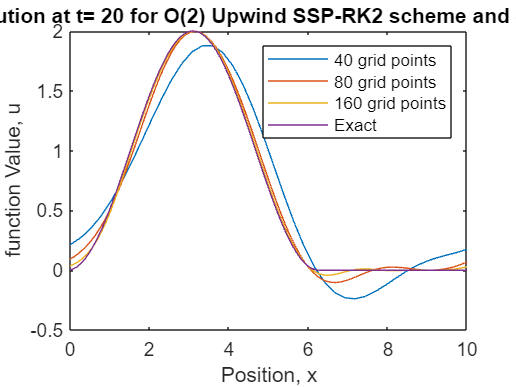


% intitialize spacial grid
U_exact = zeros([grid_size,1]); % add extra cels to simulate the periodic boundary condition

% obtain exact solution
for i = 1:length(U_exact)
    x = i*Delta_x; % position
    arg = x - t_end; % argument to function that defines wave
    arg = mod(arg,domainWidth);
    % apply function (compute exact soln)
    if(arg <= 2*pi)
        U_exact(i) = 1-cos(arg);
    else
        U_exact(i)= 0;
    end
end

plot(xSpace,U_exact);
title("Solution at t= 20 for O(2) Upwind SSP-RK2 scheme and exact)",Interpreter="tex");
xlabel("Position, x"); ylabel("function Value, u");
legend([legendString,"Exact"]);


errors

errors =     2.0336    0.3808    0.0627



log2(errors(1)) - log2(errors(2))

ans = 2.4168

log2(errors(2)) - log2(errors(3))

ans = 2.6032

(log2(errors(1)) - log2(errors(3))) / 2

ans = 2.5100

function res = residual(U, sigma)
    res = sigma/2 * ( 3 * U(3:end) - 4 * U(2:end-1) + U(1:end-2));
end